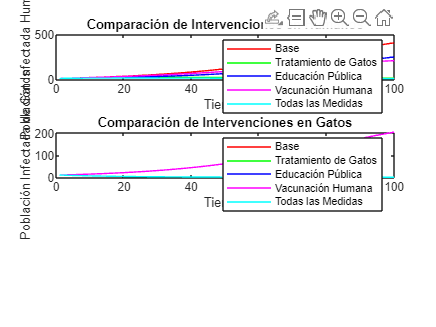

%%%Coded by Santiago Caballero Rosas,%%%

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%       |\      _,,,---,,_                 %
% ZZZzz /,`.-'`'    -.  ;-;;,_             %
%      |,4-  ) )-,_. ,\ (  `'-'            %
%     '---''(_/--'  `-'\_)  Modelo SIR-CAT % 
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

              %%%PREGUNTA VI%%%
              %SALUD PÚBLICA%

% Parámetros base revisados
beta = 0.0001; % Tasa de infección ajustada
gamma_H = 0.01; % Tasa de recuperación en humanos
gamma_G_base = 0.01; % Tasa de recuperación en gatos (base)
psi = 0.01; % Tasa de vacunación en humanos
phi = 0.5; % Reducción de la tasa de infección debido a campañas de educación

% Valores iniciales revisados
S_H0 = 1000;
I_H0 = 10; % pequeña infección inicial
T_H0 = 0;
S_G0 = 500;
I_G0 = 10; % pequeña infección inicial

t_max = 100;

% Simulación del escenario base
[S_H_base, I_H_base, T_H_base, S_G_base, I_G_base] = simulate_scenario(beta, gamma_H, gamma_G_base, 0, 0, S_H0, I_H0, T_H0, S_G0, I_G0, t_max);

% Simulación del escenario 1: Tratamiento Intensivo de Gatos
gamma_G_treatment = 0.1; % Tasa de recuperación en gatos aumentada
[S_H_treatment, I_H_treatment, T_H_treatment, S_G_treatment, I_G_treatment] = simulate_scenario(beta, gamma_H, gamma_G_treatment, 0, 0, S_H0, I_H0, T_H0, S_G0, I_G0, t_max);

% Simulación del escenario 2: Campañas de Educación Pública
[S_H_education, I_H_education, T_H_education, S_G_education, I_G_education] = simulate_scenario(beta, gamma_H, gamma_G_base, 0, phi, S_H0, I_H0, T_H0, S_G0, I_G0, t_max);

% Simulación del escenario 3: Vacunación de Humanos
[S_H_vaccination, I_H_vaccination, T_H_vaccination, S_G_vaccination, I_G_vaccination] = simulate_scenario(beta, gamma_H, gamma_G_base, psi, 0, S_H0, I_H0, T_H0, S_G0, I_G0, t_max);

% Simulación del escenario 4: Todas las Medidas
[S_H_all, I_H_all, T_H_all, S_G_all, I_G_all] = simulate_scenario(beta, gamma_H, gamma_G_treatment, psi, phi, S_H0, I_H0, T_H0, S_G0, I_G0, t_max);

% Graficar los resultados
figure;

% Dinámica de la población humana
subplot(3, 1, 1);
plot(1:t_max, I_H_base, 'r', 'DisplayName', 'Base');
hold on;
plot(1:t_max, I_H_treatment, 'g', 'DisplayName', 'Tratamiento de Gatos');
plot(1:t_max, I_H_education, 'b', 'DisplayName', 'Educación Pública');
plot(1:t_max, I_H_vaccination, 'm', 'DisplayName', 'Vacunación Humana');
plot(1:t_max, I_H_all, 'c', 'DisplayName', 'Todas las Medidas');
xlabel('Tiempo');
ylabel('Población Infectada Humana');
title('Comparación de Intervenciones en Humanos');
legend;
hold off;

% Dinámica de la población de gatos
subplot(3, 1, 2);
plot(1:t_max, I_G_base, 'r', 'DisplayName', 'Base');
hold on;
plot(1:t_max, I_G_treatment, 'g', 'DisplayName', 'Tratamiento de Gatos');
plot(1:t_max, I_G_education, 'b', 'DisplayName', 'Educación Pública');
plot(1:t_max, I_G_vaccination, 'm', 'DisplayName', 'Vacunación Humana');
plot(1:t_max, I_G_all, 'c', 'DisplayName', 'Todas las Medidas');
xlabel('Tiempo');
ylabel('Población Infectada de Gatos');
title('Comparación de Intervenciones en Gatos');
legend;
hold off;


% Función para simular el escenario

function [S_H, I_H, T_H, S_G, I_G] = simulate_scenario(beta, gamma_H, gamma_G, psi, phi, S_H0, I_H0, T_H0, S_G0, I_G0, t_max)
    S_H = zeros(1, t_max);
    I_H = zeros(1, t_max);
    T_H = zeros(1, t_max);
    S_G = zeros(1, t_max);
    I_G = zeros(1, t_max);

    % Valores iniciales
    S_H(1) = S_H0;
    I_H(1) = I_H0;
    T_H(1) = T_H0;
    S_G(1) = S_G0;
    I_G(1) = I_G0;

    % Simulación
    for t = 1:t_max-1
        dS_H = -beta * I_G(t) * S_H(t) * (1 - phi) - psi * S_H(t);
        dI_H = beta * I_G(t) * S_H(t) * (1 - phi) - gamma_H * I_H(t);
        dT_H = gamma_H * I_H(t) + psi * S_H(t);
        dS_G = -beta * I_G(t) * S_G(t);
        dI_G = beta * I_G(t) * S_G(t) - gamma_G * I_G(t);

        S_H(t+1) = S_H(t) + dS_H;
        I_H(t+1) = I_H(t) + dI_H;
        T_H(t+1) = T_H(t) + dT_H;
        S_G(t+1) = S_G(t) + dS_G;
        I_G(t+1) = I_G(t) + dI_G;
    end
end